clear all
numfiles = 100000; %100000
mydata = cell(1, numfiles);

for k = 1:numfiles
  myfilename = sprintf('C2--waveforms--%05d.txt', k-1);
  delimiterIn = ',';
  headerlinesIn = 5;
  mydata{k} = importdata(myfilename, delimiterIn,headerlinesIn);
end

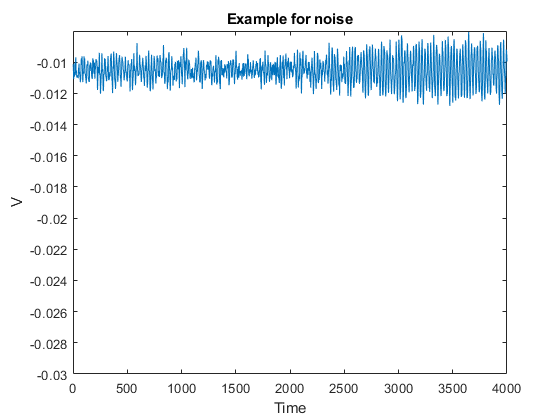

plot(mydata{1}.data(:,2))
axis([0 4000 -.03 -.008])
title 'Example for noise';
xlabel 'Time';
ylabel 'V'; 

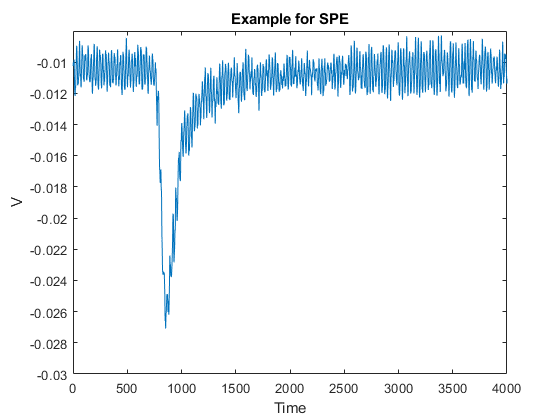

plot(mydata{900}.data(:,2))
axis([0 4000 -.03 -.008])
title 'Example for SPE';
xlabel 'Time';
ylabel 'V'; 

%% start preprocessing of data - feature engineering

amp_Spe=zeros(1,k);
for a=1:k
    amp_Spe(a)=min(mydata{a}.data(:,2));
end


ha = histogram(amp_Spe)

ha =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×111 double]
          NumBins: 111
         BinEdges: [1×112 double]
         BinWidth: 3.0000e-04
        BinLimits: [-0.0438 -0.0105]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


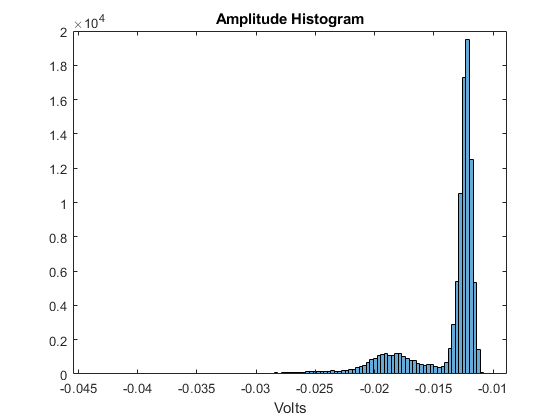

title 'Amplitude Histogram';
xlabel 'Volts';

mean(amp_Spe)

ans = -0.0139

q_spe=zeros(1,k);
for a=1:k
    q_spe(a)=trapz(mydata{a}.data(:,2));
end
hq = histogram(q_spe)

hq =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×233 double]
          NumBins: 233
         BinEdges: [1×234 double]
         BinWidth: 0.1000
        BinLimits: [-53 -29.7000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


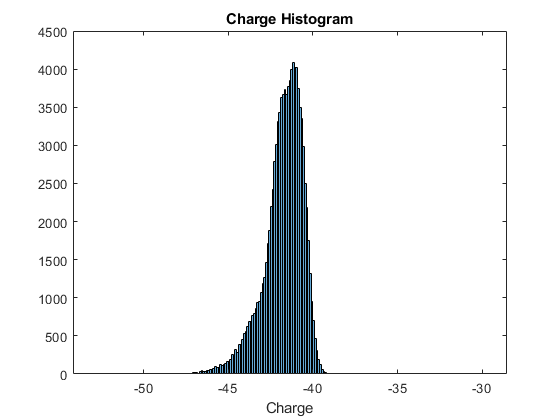

title 'Charge Histogram';
xlabel 'Charge';

mean(q_spe)

ans = -41.7358

max_1st_der=zeros(1,k);
for a=1:k
    max_1st_der(a)=min(diff(mydata{a}.data(:,2)));
end

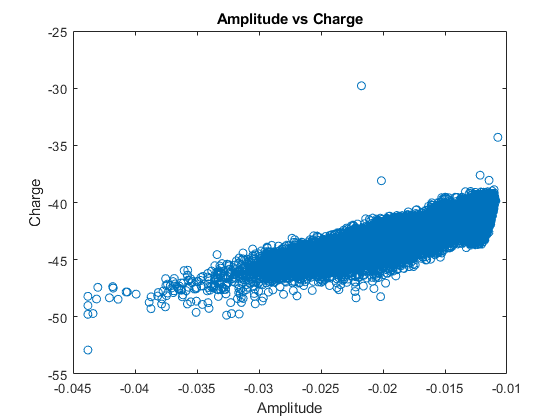

plot(amp_Spe,q_spe,'o')
title 'Amplitude vs Charge';
xlabel 'Amplitude';
ylabel 'Charge';

X=cat(2,amp_Spe', q_spe');

# Cluster Gaussian Mixture Data Using Hard Clustering

This example shows how to implement hard clustering on simulated data from a mixture of Gaussian distributions. 

Gaussian mixture models can be used for clustering data, by realizing that the multivariate normal components of the fitted model can represent clusters.

## Simulate Data from a Mixture of Gaussian Distributions

Simulate data from a mixture of two bivariate Gaussian distributions using [`mvnrnd`](docid:stats_ug.f1130139).

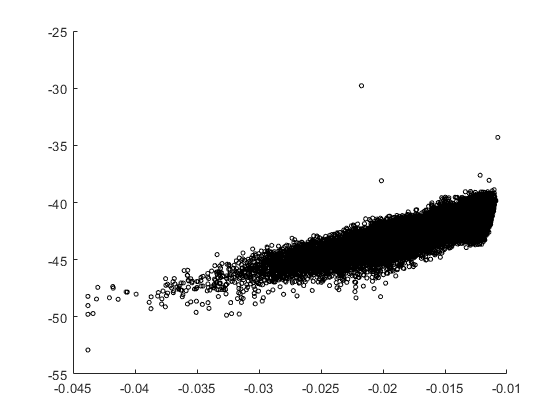

% rng('default')  % For reproducibility
% mu1 = [1 2];
% sigma1 = [3 .2; .2 2];
% mu2 = [-1 -2];
% sigma2 = [2 0; 0 1];
% X = [mvnrnd(mu1,sigma1,200); mvnrnd(mu2,sigma2,100)];
% n = size(X,1);

figure
scatter(X(:,1),X(:,2),10,'ko')

## Fit the Simulated Data to a Gaussian Mixture Model

Fit a two-component Gaussian mixture model (GMM). Here, you know the correct number of components to use. In practice, with real data, this decision would require comparing models with different numbers of components. Also, request to display the final iteration of the expectation-maximization fitting routine.

options = statset('Display','final'); 
gm = fitgmdist(X,3,'Options',options)

39 iterations, log-likelihood = 418919

gm = 

Gaussian mixture distribution with 3 components in 2 dimensions
Component 1:
Mixing proportion: 0.753025
Mean:   -0.0123  -41.2982

Component 2:
Mixing proportion: 0.038374
Mean:   -0.0236  -44.4561

Component 3:
Mixing proportion: 0.208601
Mean:   -0.0179  -42.8151





Plot the estimated probability density contours for the two-component mixture distribution. The two bivariate normal components overlap, but their peaks are distinct. This suggests that the data could reasonably be divided into two clusters.

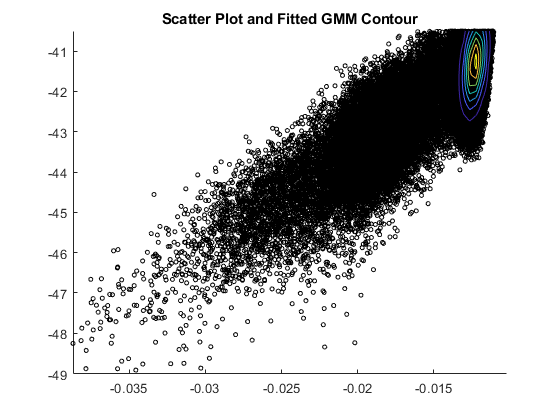

hold on
gmPDF = @(x,y)reshape(pdf(gm,[x(:) y(:)]),size(x));
fcontour(gmPDF)
title('Scatter Plot and Fitted GMM Contour')

hold off
xlim([-0.0387 -0.0102])
ylim([-49.01 -40.50])

## Cluster the Data Using the Fitted GMM

[`cluster`](docid:stats_ug.brx2uny-1) implements "hard clustering", a method that assigns each data point to exactly one cluster. For GMM, `cluster` assigns each point to one of the two mixture components in the GMM. The center of each cluster is the corresponding mixture component mean. For details on "soft clustering," see [Cluster Gaussian Mixture Data Using Soft Clustering](docid:stats_ug.buqq83f).

Partition the data into clusters by passing the fitted GMM and the data to `cluster`.

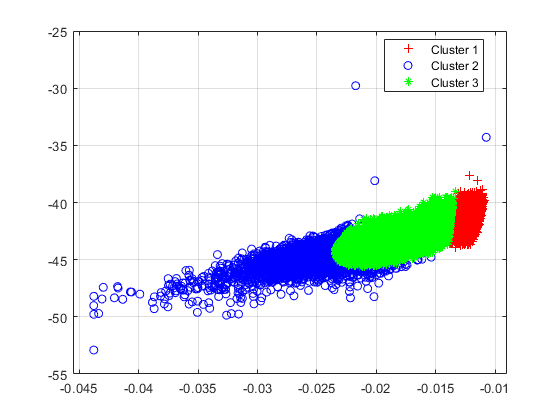

lc1 = 76237

idx = cluster(gm,X);
cluster1 = (idx == 1); % |1| for cluster 1 membership
cluster2 = (idx == 2); % |2| for cluster 2 membership
cluster3 = (idx == 3); % |2| for cluster 2 membership

figure
gscatter(X(:,1),X(:,2),idx,'rbg','+o*')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')
grid on

Each cluster corresponds to one of the bivariate normal components in the mixture distribution. `cluster` assigns data to clusters based on a cluster membership score. Each cluster membership scores is the estimated posterior probability that the data point came from the corresponding component. `cluster` assigns each point to the mixture component corresponding to the highest posterior probability.

You can estimate cluster membership posterior probabilities by passing the fitted GMM and data to either:

- [`posterior`](docid:stats_ug.brx2uys-1)

- `cluster`, and request to return the third output argument

lc1 = nnz(cluster1)

   76.2370



display(lc1/k*100)

lc2 = 2559

lc2 = nnz(cluster2)

    2.5590



display(lc2/k*100)

lc3 = 21204

lc3 = nnz(cluster3)

   21.2040



display(lc3/k*100)


## Estimate Cluster Membership Posterior Probabilities

Estimate and plot the posterior probability of the first component for each point.

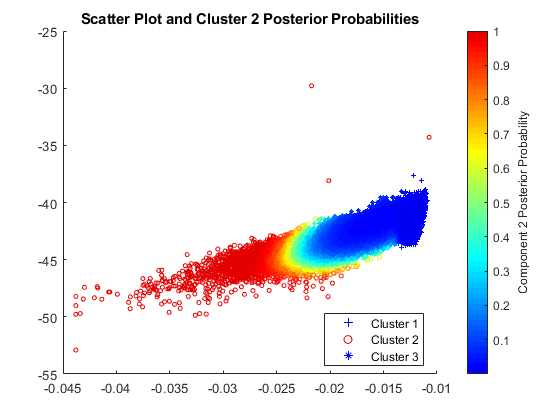

P = posterior(gm,X); 

figure
scatter(X(cluster1,1),X(cluster1,2),10,P(cluster1,2),'+')
hold on
scatter(X(cluster2,1),X(cluster2,2),10,P(cluster2,2),'o')
hold on
scatter(X(cluster3,1),X(cluster3,2),10,P(cluster3,2),'*')

hold off
clrmap = jet(80);
colormap(clrmap(9:72,:))
ylabel(colorbar,'Component 2 Posterior Probability')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')

title('Scatter Plot and Cluster 2 Posterior Probabilities')

`P2` is an `n`-by-2 matrix of cluster membership posterior probabilities. The first column contains the probabilities for cluster 1 and the second column corresponds to cluster 2.

## Estimate Cluster Membership Posterior Probabilities

Estimate and plot the posterior probability of the first component for each point.

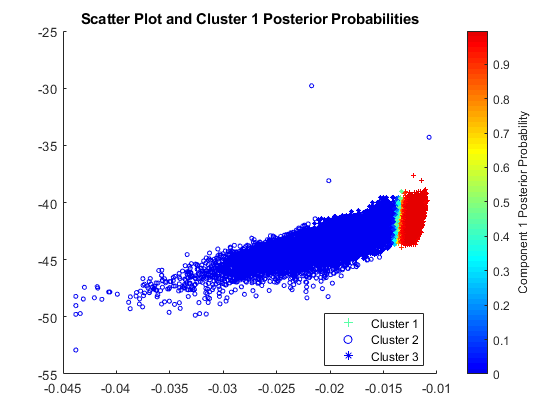


figure
scatter(X(cluster1,1),X(cluster1,2),10,P(cluster1,1),'+')
hold on
scatter(X(cluster2,1),X(cluster2,2),10,P(cluster2,1),'o')
hold on
scatter(X(cluster3,1),X(cluster3,2),10,P(cluster3,1),'*')

hold off
clrmap = jet(80);
colormap(clrmap(9:72,:))
ylabel(colorbar,'Component 1 Posterior Probability')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')

title('Scatter Plot and Cluster 1 Posterior Probabilities')

`P` is an `n`-by-2 matrix of cluster membership posterior probabilities. The first column contains the probabilities for cluster 1 and the second column corresponds to cluster 2.

## Estimate Cluster Membership Posterior Probabilities

Estimate and plot the posterior probability of the first component for each point.

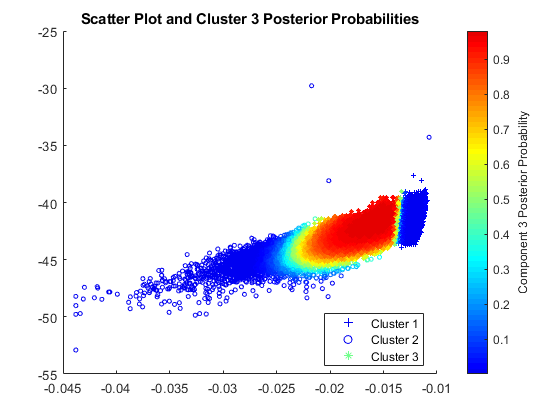

figure
scatter(X(cluster1,1),X(cluster1,2),10,P(cluster1,3),'+')
hold on
scatter(X(cluster2,1),X(cluster2,2),10,P(cluster2,3),'o')
hold on
scatter(X(cluster3,1),X(cluster3,2),10,P(cluster3,3),'*')

hold off
clrmap = jet(80);
colormap(clrmap(9:72,:))
ylabel(colorbar,'Component 3 Posterior Probability')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')
title('Scatter Plot and Cluster 3 Posterior Probabilities')

`P3` is an `n`-by-2 matrix of cluster membership posterior probabilities. The first column contains the probabilities for cluster 1 and the second column corresponds to cluster 3.

c1=find(cluster1);
c2=find(cluster2);
c3=find(cluster3);

c1_amp=zeros(1,lc1);
c1_q=zeros(1,lc1);

c2_amp=zeros(1,lc2);
c2_q=zeros(1,lc2);

c3_amp=zeros(1,lc3);
c3_q=zeros(1,lc3);


for a=1:lc1
    c1_amp(a) = amp_Spe(c1(a));
    c1_q(a) = q_spe(c1(a));
end

for a=1:lc2
    c2_amp(a) = amp_Spe(c2(a));
    c2_q(a) = q_spe(c2(a));
end

for a=1:lc3
    c3_amp(a) = amp_Spe(c3(a));
    c3_q(a) = q_spe(c3(a));
end

hc1a = histogram(c1_amp,'facealpha',.5,'edgecolor','auto')

hc1a =   Histogram with properties:

             Data: [1×76237 double]
           Values: [1×61 double]
          NumBins: 61
         BinEdges: [1×62 double]
         BinWidth: 5.0000e-05
        BinLimits: [-0.0139 -0.0108]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'auto'

  Show all properties



xlabel 'Volts';
mean(c1_amp)

ans = -0.0123

hold on

hc2a = histogram(c2_amp,'facealpha',.5,'edgecolor','auto')

hc2a =   Histogram with properties:

             Data: [1×2559 double]
           Values: [6 2 3 2 1 5 11 16 18 15 37 31 51 77 113 190 258 348 385 412 398 85 29 30 16 9 6 3 1 0 0 0 0 1]
          NumBins: 34
         BinEdges: [1×35 double]
         BinWidth: 0.0010
        BinLimits: [-0.0440 -0.0100]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'auto'

  Show all properties



xlabel 'Volts';
mean(c2_amp)

ans = -0.0263


hc3a = histogram(c3_amp,'facealpha',.5,'edgecolor','auto')

hc3a =   Histogram with properties:

             Data: [1×21204 double]
           Values: [19 90 120 157 202 240 264 347 417 512 674 830 875 1064 1136 1199 1089 1048 1207 1216 1036 884 811 797 599 545 496 549 531 436 401 452 672 287 2]
          NumBins: 35
         BinEdges: [1×36 double]
         BinWidth: 3.0000e-04
        BinLimits: [-0.0237 -0.0132]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'auto'

  Show all properties


title 'Amplitude Histogram by Cluster';
xlabel 'Volts';
mean(c3_amp)

ans = -0.0181

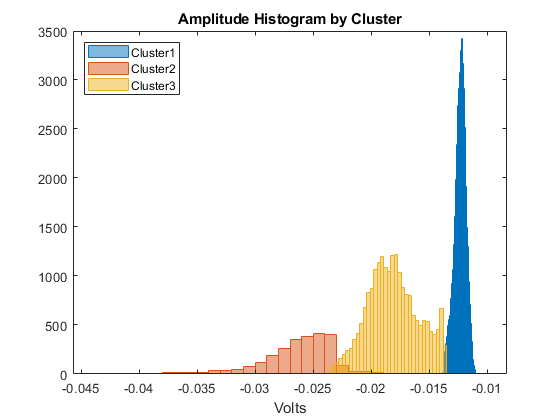

legend('Cluster1','Cluster2','Cluster3','location','northwest')
hold off

hc1q = histogram(c1_q,'facealpha',.5,'edgecolor','none')

hc1q =   Histogram with properties:

             Data: [1×76237 double]
           Values: [1×127 double]
          NumBins: 127
         BinEdges: [1×128 double]
         BinWidth: 0.0500
        BinLimits: [-43.9500 -37.6000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


mean(c1_q)

ans = -41.3001


hold on

hc2q = histogram(c2_q, 'facealpha',.5,'edgecolor','none')

hc2q =   Histogram with properties:

             Data: [1×2559 double]
           Values: [1 0 0 0 0 0 0 0 0 0 1 5 2 3 10 9 12 18 33 31 52 88 118 167 256 282 272 289 241 221 181 117 74 29 24 12 5 2 1 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1]
          NumBins: 78
         BinEdges: [1×79 double]
         BinWidth: 0.3000
        BinLimits: [-53.1000 -29.7000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


mean(c2_q)

ans = -45.1253


hc3q = histogram(c3_q, 'facealpha',.5,'edgecolor','none')

hc3q =   Histogram with properties:

             Data: [1×21204 double]
           Values: [1 4 17 30 39 54 73 72 100 149 157 232 217 304 310 386 470 501 558 645 645 721 744 787 813 824 851 909 848 869 862 813 851 750 695 698 629 530 481 394 335 296 269 219 199 161 133 114 85 86 73 39 33 36 26 22 16 9 3 4 5 7 0 0 0 0 1]
          NumBins: 67
         BinEdges: [1×68 double]
         BinWidth: 0.1000
        BinLimits: [-45.7000 -39]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


title 'Charge Histogram by Cluster';
xlabel 'Charge';
legend('Cluster1','Cluster2','Cluster3','location','northwest')
mean(c3_q)

ans = -42.8934

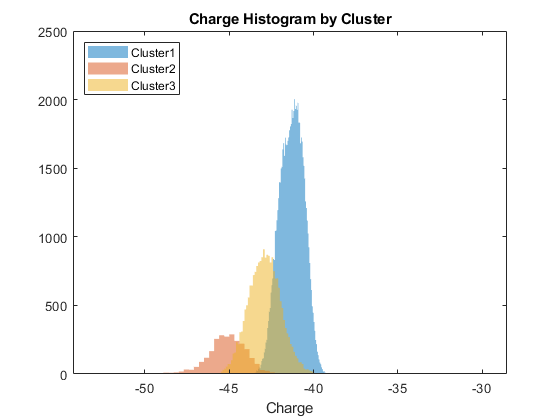

hold off

Fs = 10e9;
cut_off=1e8/Fs/2;
order=64;
h=fir1(order,cut_off);



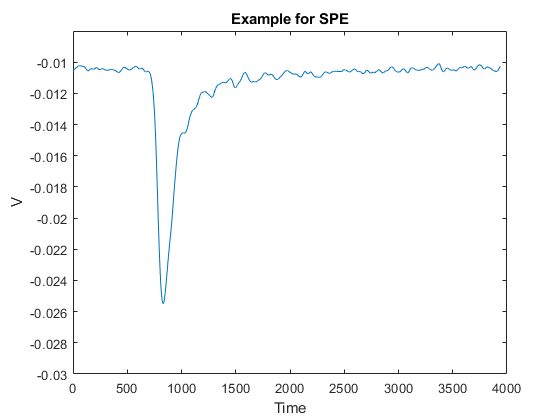

con=conv(mydata{900}.data(:,2),h,'valid');

plot(con)
title 'Example for SPE';
xlabel 'Time';
ylabel 'V'; 
axis([0 4000 -.03 -.008])

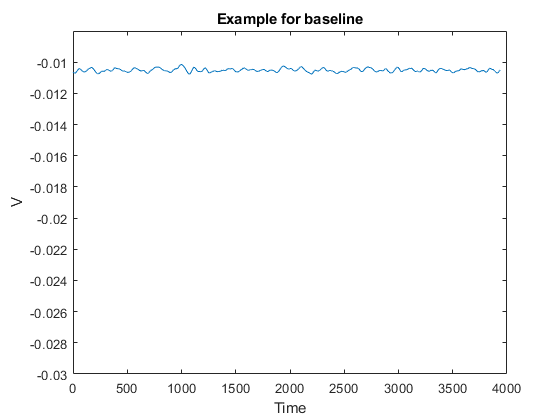

con=conv(mydata{1}.data(:,2),h,'valid');

plot(con)
title 'Example for baseline';
xlabel 'Time';
ylabel 'V'; 
axis([0 4000 -.03 -.008])

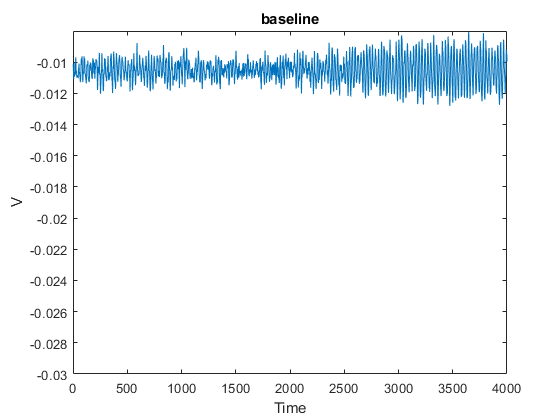


plot(mydata{1}.data(:,2))
title 'baseline';
xlabel 'Time';
ylabel 'V'; 
axis([0 4000 -.03 -.008])

len_conv=length(conv(mydata{1}.data(:,2),h,'valid'));
conv_data=zeros(k,len_conv);
conv_amp=zeros(1,k);
conv_q=zeros(1,k);
for a=1:k
    conv_data(a,:)=conv(mydata{a}.data(:,2),h,"valid");
    conv_amp(a)=min(conv_data(a,:));
    conv_q(a)=trapz(conv_data(a,:));
end

hca = histogram(conv_amp)

hca =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×116 double]
          NumBins: 116
         BinEdges: [1×117 double]
         BinWidth: 3.0000e-04
        BinLimits: [-0.0438 -0.0090]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


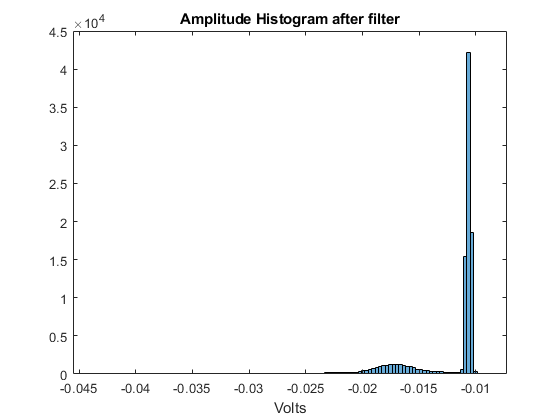

title 'Amplitude Histogram after filter';
xlabel 'Volts';

mean(conv_amp)

ans = -0.0123

hq = histogram(conv_q)

hq =   Histogram with properties:

             Data: [1×100000 double]
           Values: [1×229 double]
          NumBins: 229
         BinEdges: [1×230 double]
         BinWidth: 0.1000
        BinLimits: [-52.3000 -29.4000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


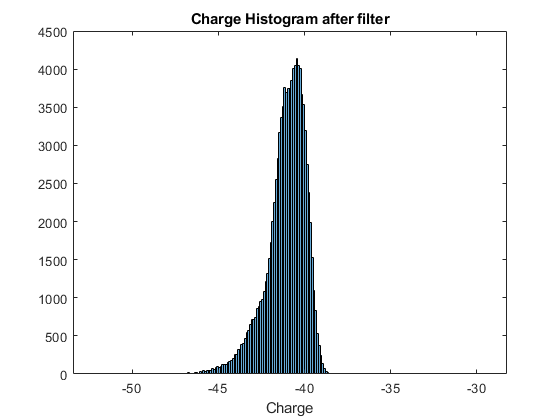

title 'Charge Histogram after filter';
xlabel 'Charge';

mean(conv_q)

ans = -41.0754

conv_X=cat(2,conv_amp', conv_q')

conv_X =    -0.0108  -41.3869
   -0.0110  -41.8091
   -0.0131  -42.6262
   -0.0108  -41.4490
   -0.0207  -43.5681
   -0.0108  -41.2575
   -0.0110  -41.2966
   -0.0109  -41.6367
   -0.0108  -41.2071
   -0.0109  -41.6413


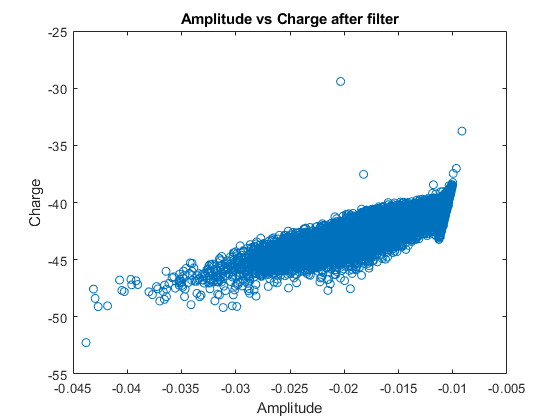

plot(conv_amp,conv_q,'o')
title 'Amplitude vs Charge after filter';
xlabel 'Amplitude';
ylabel 'Charge';

c_options = statset('Display','final'); 
c_gm = fitgmdist(conv_X,3,'Options',options)

13 iterations, log-likelihood = 587651

c_gm = 

Gaussian mixture distribution with 3 components in 2 dimensions
Component 1:
Mixing proportion: 0.759602
Mean:   -0.0106  -40.6372

Component 2:
Mixing proportion: 0.035791
Mean:   -0.0223  -43.9226

Component 3:
Mixing proportion: 0.204607
Mean:   -0.0167  -42.2041





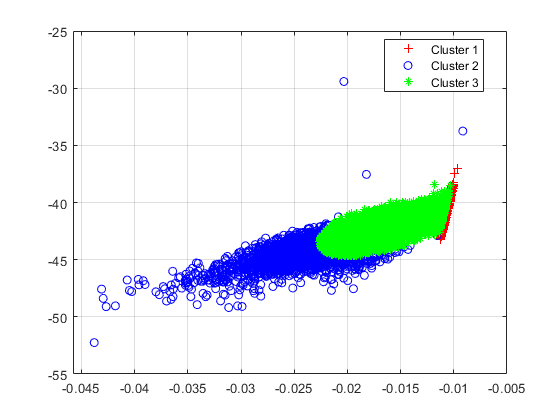

c_idx = cluster(c_gm,conv_X);
cluster1 = (c_idx == 1); % |1| for cluster 1 membership
cluster2 = (c_idx == 2); % |2| for cluster 2 membership
cluster3 = (c_idx == 3); % |2| for cluster 2 membership

figure
gscatter(conv_X(:,1),conv_X(:,2),c_idx,'rbg','+o*')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')
grid on

lc1 = nnz(cluster1)

lc1 = 76082

display(lc1/k*100)

   76.0820



lc2 = nnz(cluster2)

lc2 = 2404

display(lc2/k*100)

    2.4040



lc3 = nnz(cluster3)

lc3 = 21514

display(lc3/k*100)

   21.5140



## Estimate Cluster Membership Posterior Probabilities

Estimate and plot the posterior probability of the first component for each point.

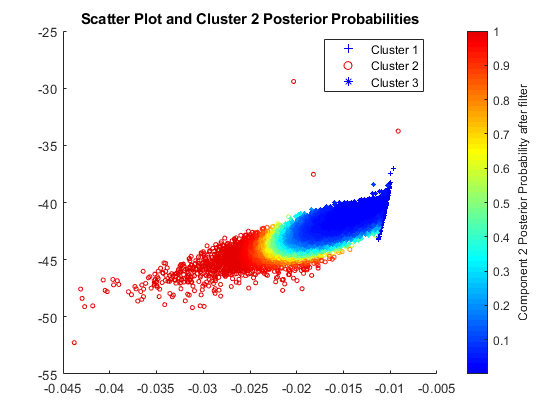

cP = posterior(c_gm,conv_X); 

figure
scatter(conv_X(cluster1,1),conv_X(cluster1,2),10,cP(cluster1,2),'+')
hold on
scatter(conv_X(cluster2,1),conv_X(cluster2,2),10,cP(cluster2,2),'o')
hold on
scatter(conv_X(cluster3,1),conv_X(cluster3,2),10,cP(cluster3,2),'*')

hold off
clrmap = jet(80);
colormap(clrmap(9:72,:))
ylabel(colorbar,'Component 2 Posterior Probability after filter')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')
title('Scatter Plot and Cluster 2 Posterior Probabilities')

`P2` is an `n`-by-2 matrix of cluster membership posterior probabilities. The first column contains the probabilities for cluster 1 and the second column corresponds to cluster 2.

## Estimate Cluster Membership Posterior Probabilities

Estimate and plot the posterior probability of the first component for each point.

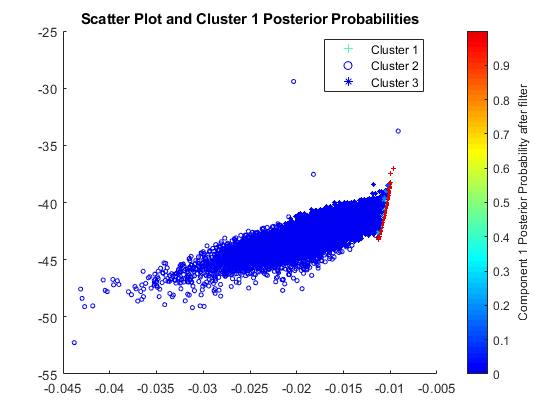


figure
scatter(conv_X(cluster1,1),conv_X(cluster1,2),10,cP(cluster1,1),'+')
hold on
scatter(conv_X(cluster2,1),conv_X(cluster2,2),10,cP(cluster2,1),'o')
hold on
scatter(conv_X(cluster3,1),conv_X(cluster3,2),10,cP(cluster3,1),'*')

hold off
clrmap = jet(80);
colormap(clrmap(9:72,:))
ylabel(colorbar,'Component 1 Posterior Probability after filter')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')
title('Scatter Plot and Cluster 1 Posterior Probabilities')

`P` is an `n`-by-2 matrix of cluster membership posterior probabilities. The first column contains the probabilities for cluster 1 and the second column corresponds to cluster 2.

## Estimate Cluster Membership Posterior Probabilities

Estimate and plot the posterior probability of the first component for each point.

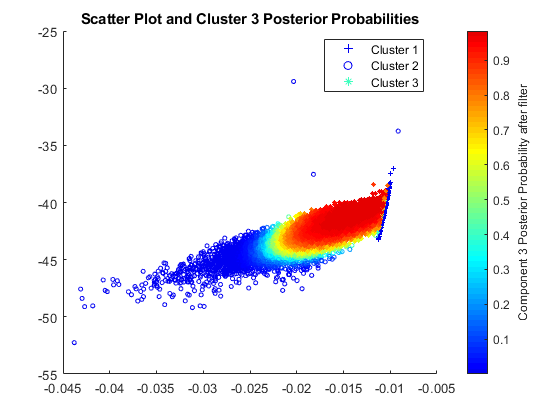

figure
scatter(conv_X(cluster1,1),conv_X(cluster1,2),10,cP(cluster1,3),'+')
hold on
scatter(conv_X(cluster2,1),conv_X(cluster2,2),10,cP(cluster2,3),'o')
hold on
scatter(conv_X(cluster3,1),conv_X(cluster3,2),10,cP(cluster3,3),'*')

hold off
clrmap = jet(80);
colormap(clrmap(9:72,:))
ylabel(colorbar,'Component 3 Posterior Probability after filter')
legend('Cluster 1','Cluster 2','Cluster 3','Location','best')
title('Scatter Plot and Cluster 3 Posterior Probabilities')

`P3` is an `n`-by-2 matrix of cluster membership posterior probabilities. The first column contains the probabilities for cluster 1 and the second column corresponds to cluster 3.

c1=find(cluster1);
c2=find(cluster2);
c3=find(cluster3);

c1_camp=zeros(1,lc1);
c1_cq=zeros(1,lc1);

c2_camp=zeros(1,lc2);
c2_cq=zeros(1,lc2);

c3_camp=zeros(1,lc3);
c3_q=zeros(1,lc3);


for a=1:lc1
    c1_camp(a) = conv_amp(c1(a));
    c1_cq(a) = conv_q(c1(a));
end

for a=1:lc2
    c2_camp(a) = conv_amp(c2(a));
    c2_cq(a) = conv_q(c2(a));
end

for a=1:lc3
    c3_camp(a) = conv_amp(c3(a));
    c3_cq(a) = conv_q(c3(a));
end


hc1a = histogram(c1_camp, 'facealpha',.5,'edgecolor','none')
title 'Cluster1 Amplitude Histogram after filter';

hc1a =   Histogram with properties:

             Data: [1×76082 double]
           Values: [1×82 double]
          NumBins: 82
         BinEdges: [1×83 double]
         BinWidth: 2.0000e-05
        BinLimits: [-0.0113 -0.0097]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


xlabel 'Volts';
mean(c1_camp)
hold on

ans = -0.0106

hc2a = histogram(c2_camp,  'facealpha',.5,'edgecolor','none')
title 'Cluster2 Amplitude Histogram after filter';

hc2a =   Histogram with properties:

             Data: [1×2404 double]
           Values: [2 2 1 3 4 0 5 7 9 18 14 27 37 34 59 88 157 240 313 371 446 317 82 52 39 37 21 9 5 3 0 0 1 0 1]
          NumBins: 35
         BinEdges: [1×36 double]
         BinWidth: 0.0010
        BinLimits: [-0.0440 -0.0090]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


xlabel 'Volts';
mean(c2_camp)


ans = -0.0249

hc1a = histogram(c3_camp,  'facealpha',.5,'edgecolor','none')
title 'Amplitude Histogram by Cluster after filter';

hc1a =   Histogram with properties:

             Data: [1×21514 double]
           Values: [23 83 100 135 139 165 205 229 300 408 504 630 695 844 961 1081 1165 1201 1251 1219 1200 1124 994 927 795 651 562 422 419 309 288 276 263 240 194 218 199 195 260 430 206 4]
          NumBins: 42
         BinEdges: [1×43 double]
         BinWidth: 3.0000e-04
        BinLimits: [-0.0228 -0.0102]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


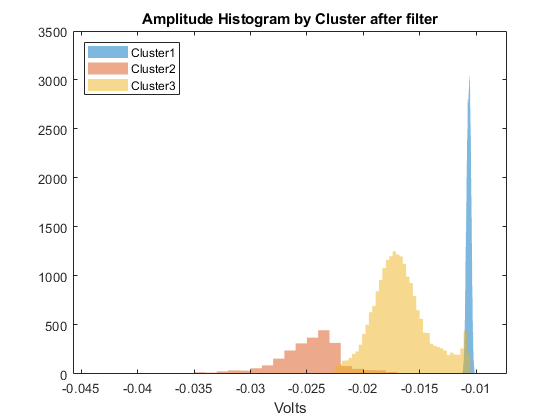

ans = -0.0167

xlabel 'Volts';
legend('Cluster1','Cluster2','Cluster3','location','northwest')
hold off
mean(c3_camp)

hc1q = histogram(c1_cq, 'facealpha',.5,'edgecolor','none')
mean(c1_cq)

hc1q =   Histogram with properties:

             Data: [1×76082 double]
           Values: [1×125 double]
          NumBins: 125
         BinEdges: [1×126 double]
         BinWidth: 0.0500
        BinLimits: [-43.2500 -37]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


hold on

ans = -40.6373

hc1q = histogram(c2_cq,  'facealpha',.5,'edgecolor','none')


hc1q =   Histogram with properties:

             Data: [1×2404 double]
           Values: [1 0 0 0 0 0 0 0 0 0 0 6 2 2 9 7 14 14 30 33 51 63 116 165 238 310 304 281 254 193 139 92 48 15 10 3 0 1 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 1]
          NumBins: 77
         BinEdges: [1×78 double]
         BinWidth: 0.3000
        BinLimits: [-52.5000 -29.4000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


mean(c2_cq)


ans = -44.6033

hc1q = histogram(c3_cq,  'facealpha',.5,'edgecolor','none')
title 'Charge Histogram by Cluster after Filter';

hc1q =   Histogram with properties:

             Data: [1×21514 double]
           Values: [13 25 65 67 89 108 167 176 238 261 312 329 424 499 525 614 679 683 709 832 815 856 849 868 925 854 897 844 844 824 746 725 670 577 523 465 361 347 295 259 239 181 156 112 91 91 73 60 36 36 29 18 11 4 6 4 5 1 0 0 0 1 1]
          NumBins: 63
         BinEdges: [1×64 double]
         BinWidth: 0.1000
        BinLimits: [-44.7000 -38.4000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: 'none'

  Show all properties


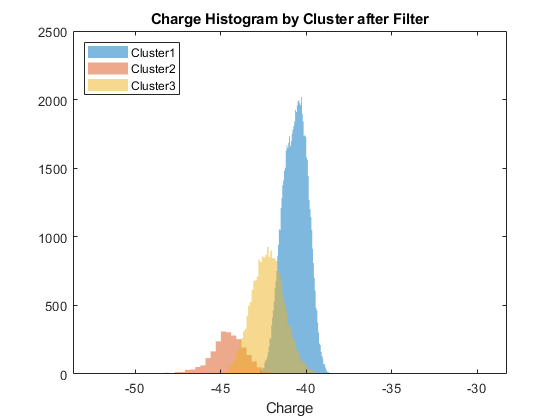

ans = -42.2304

xlabel 'Charge';
legend('Cluster1','Cluster2','Cluster3','location','northwest')
hold off
mean(c3_cq)

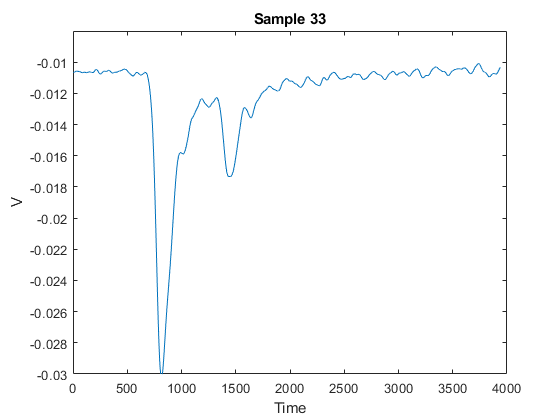

plot(conv_data(33,:))
axis([0 4000 -.03 -.008])
title 'Sample 33';
xlabel 'Time';
ylabel 'V'; 

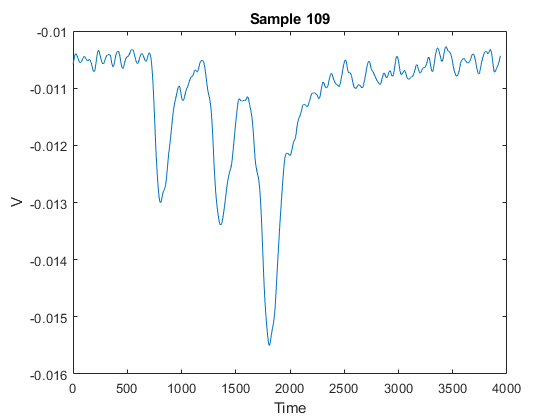

plot(conv_data(109,:))
title 'Sample 109';
xlabel 'Time';
ylabel 'V'; 
